# Script04＿Simulinkによる状態平均化モデルとSimscapeの電気回路モデルの比較

Copyright (c) 2022, The MathWorks, Inc.All rights reserved.

Simulinkによる状態平均化モデルはコンバータが持つ各状態やパラメータの関係性が理解しやすい

理論ベースの式であるため、制御設計において有効である。

一方で回路設計者にとっては回路図ベースの電気回路シミュレーションモデルのほうが回路の状態を理解しやすい。

このように、立場の違う設計者同士では自分自身の業務や理解にとって都合のよいモデルを使う傾向にあるが、

この両者で別のツールを用いていると設計情報の一致性やシミュレーションモデルの粒度の違いについて議論する際に

共通の環境下で比較検討が行えず、設計の反映漏れや互いに意思疎通の齟齬による設計ミスが発生し

設計のあと段階で発覚してしまうことが起こる可能性がある。

このスクリプトでは

**理論ベース式である状態平均化モデルと回路シミュレータモデルが**

**共存できる環境を構築し、両者に同じ信号を入力した際の出力を比較することを示す。**

**このような環境は、両モデルが持つパラメータや、抽象度の違いが**

**シミュレーション出力にどのように影響をおよぼすかを理解する手助けになる。**

## 0.モデルを用意する

検討として下記モデルを用いる。

clear variables
open_system("Model\Script04_Model\Diff_Simulink_SimscapeModel.slx");

## 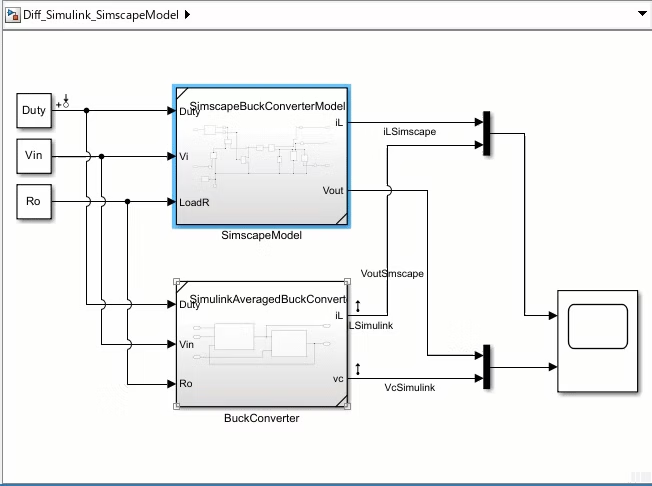

2つのサブシステムを用意して、

- 上はSimscapeのバックコンバータ回路モデル

- 下はSimulinkの状態平均化モデル

というように一つのモデルファイル内で用意した。

両者には共通の入力が定義されているため、両者の粒度やパラメータ影響度に違いがなければ

両モデルの出力は一致するはずである。

**このような検討方法はBuck-to-Buck Testと呼ばれるもので、**

**おもにモデルから自動生成されたCコードの実行結果と、**

**生成元のモデル実行結果を比較することでコード生成結果の妥当性を検証する場面でよく使われる手法である。**

**今回の例はBuck-to-Buck Testが一般的に利用されるソフトウェア設計領域とは異なるが、**

**異なる抽象度のモデルを比較するというBuck to Buck Testの考え方が物理モデリングの検証にも一部活用できることを示す。**

## 1.パラメータの設定

パラメータは下記のように設定する。

Simscape側には直流抵抗成分 ESRやインダクタンスの直流抵抗成分などの要素を追加してモデリングしてみたので

そのパラメータも含まれている。

C1 = 300e-6;%[F]
esr = 1e-4;%[Ohm]

L1 = 200e-6;%[H]
l1r =1e-4; %[Ohm]

fsw = 20000;%{Hz]
Tsw = 1 / fsw;%[Sec]

HighVth = 10;
LowVth = 10;

Ro = 5;
Vin = 12;
Duty = 0.5;


## 2.シミュレーションを実行してスイッチングモデルと平均化モデルの挙動比較

このパラメータでモデルをMATLABからキックして動かす。

このスクリプトでは2つのモデルの出力を比較してみた。

Simdata = sim("Model\Script04_Model\Diff_Simulink_SimscapeModel.slx");


for i = 1:2
    subplot(2,1,i)
    Simdata.ScopeData{i}.Values.plot()
    grid on;
end
subplot(2,1,1)
ylabel('IL')
legend('Simscape','Simulink');
subplot(2,1,2)
legend('Simscape','Simulink');
ylabel('Vout')

上がコイル電流、下が出力電圧になっているが、わりと一致しているようにみえる。

上のグラフを拡大すると

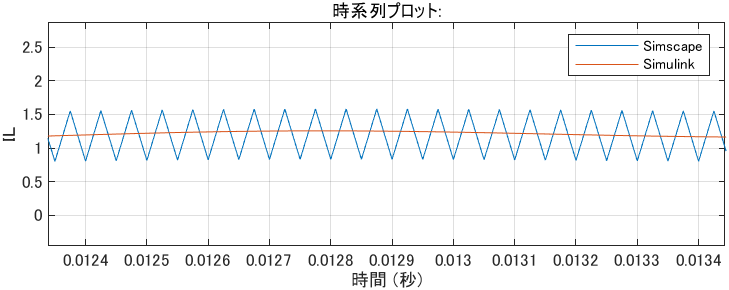

SimscapeはちゃんとPWMでスイッチングしているのでリップルがあるが

Simulinkは平均化されているのでリップルがない

でも平均値としては一致した応答になっているのもわかる。

この場合では両モデルの抽象度やパラメータが一致しており、

制御設計においてSimulinkモデルをベースに設計したとしても差し支えないと考えることができる。

## 3.パラメータを更新して再度シミュレーション(実回路の寄生成分の影響）

次はあえてパラメータによって両者のモデル挙動に変化がある例を示す。

このように一致しない結果を得た場合はSimulinkを扱う制御設計者は回路設計者とその違いの原因について議論することで

両者の共通見解としての原因を明らかにし、その違いを許容するか、設計に反映させるかを判断しなければならない。

このような比較ができる環境がその判断を助ける情報を提供してくれる。

コンデンサの直流抵抗成分:esr

インダクタの直流抵抗成分:l1r

を増加した際の応答を比較する。

これらのパラメータは実際の回路には必ず存在する要素だが

今回あえてSimulink側の微分方程式には定義しなかった。

そのため、理想となる理論式と実際の回路には差異があることが確認できる。

**ここで、理論と実際の結果の違いを鑑みて、**

**モデルに対してどこまでの要素を含めるのが妥当なのかを判断することが大切である。**

esr = 1e-1;%[Ohm]
l1r = 1e-2; %[Ohm]

Simdata = sim("Model\Script04_Model\Diff_Simulink_SimscapeModel.slx");


figure;
for i = 1:2
    subplot(2,1,i)
    Simdata.ScopeData{i}.Values.plot()
    grid on;
end
subplot(2,1,1)
ylabel('IL')
legend('Simscape','Simulink');
subplot(2,1,2)
legend('Simscape','Simulink');
ylabel('Vout')

このグラフからESRやインダクタの直流抵抗成分が振動減衰性に依存していることがうかがえる。

このようなパラメータの影響度を考えると、ESRやインダクタの直流抵抗がそれなりに存在し、無視できない場合は

Simulinkで構築した状態平均化モデルをこれらのパラメータを含めた形で立て直すか、

Simulinkの状態平均化モデルで補償器の構成（たとえばPIで構築するか、Type2補償器なのか、Type3なのか）を決定し、

パラメータの微調整をSimscapeモデルで行うといった手法が考えられる。

このように、結果が不一致となった場合でも作成したモデルはそれぞれ無駄になることはなく、

設計の指標を考える足がかりとして活用することができる。

また、前述した通り、数式ベース、回路ベースのモデルを同一環境で比較できるので、

制御担当者と回路担当者間で共通した議論の土台としてこのモデル環境が有効になる。

そのため　複数のエンジニアで協力して遂行するプロジェクトにおいて　このような比較検討のためのモデル環境が有効であると考える。

#### 3.1  周波数スイープによるSimscapeモデルに対する伝達関数推定

今回はステップ応答で周波数特性の変化を観測したが、ボード線図上でその特性の違いを確認したい。

Simulinkでモデリングされた数式モデルはScript03で示されたような線形化によって伝達関数を取得することができる。

一方でSimscapeは電気回路モデルであるため、数式としてモデリングされていないため、別の手法が必要になる。

これはシミュレータの回路定式化の手法がSimulikとSimscapeで異なっているためである。

これまで述べてきたように状態平均化法によってSimulinkのモデルはPWM1周期分の振る舞いが平均化されて

「微分方程式としてモデリング」されるため、定常状態近傍での偏微分演算が可能になるため、線形化が可能である。

一方　Simscape側ではデバイスのPWMスイッチングの振る舞いを精度良く表現できるように、修正接点解析法を用いている。[4]

PWMによって時間的にONとOFFを繰り返す非線形なモデルは偏微分によって線形化できないため、

外部から正弦波信号を入力した際の出力応答の振幅、および位相変化に基づいて「周波数特性を推定する」という手法を用いる。

## Simulink モデルのモデル操作点での周波数特性の推定

[https://jp.mathworks.com/help/slcontrol/ug/linearize-simulink-model.html](https://jp.mathworks.com/help/slcontrol/ug/linearize-simulink-model.html)

#### **操作１：伝達関数における入力を指定する。**

１．Dutyが入力されている信号線を右クリックし右クリックメニューを開く

 2. 線形解析ポイントから入力の摂動を選択 

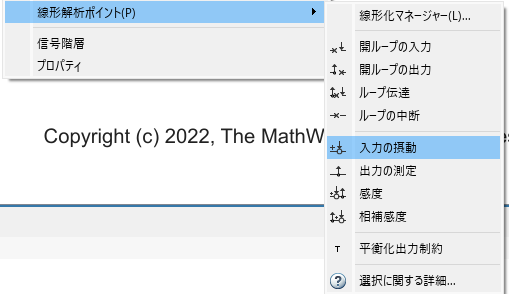

次に出力を指定する。

今回伝達関数の解析を行うのはVout（Vc)のみとする。

モデリングや条件を設定すればiLに対しての推定を行うこともできるが、

Simulinkモデリングの結果からもわかるように　電流のダイナミクスを示す式にはVcからのフィードバックが存在する。

そのため、Simscape回路で推定を行おうとするとDutyからの外乱とVout(Vc)からの両方の外乱の影響が混在して

電流波形に重畳するため、原理上影響の分離が難しくなるためである。

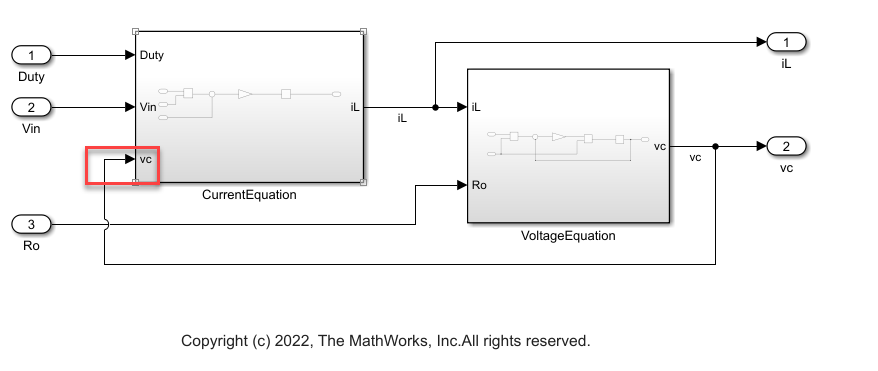

出力を指定する場合は同様に右クリックメニューから

１．信号解析ポイントを選択

２．”出力の測定”を選択

をおこなう。これをSimscape サブシステムの出力側のVout(Vc)に行う。

**＃注意：モデルの他の信号ににすでに解析ポイントが設定されている場合、結果が変化してしまうので一度モデルのすべての信号を調べて他に解析ポイントが設定されていないか確認する必要がある。**

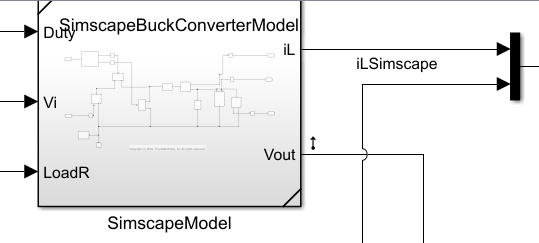

#### **操作２：”Simulink Control Design”の”モデル線形器アプリを使う**

上部ツールストリップから

- ”アプリ”タブの選択

- モデル線形化器アプリをクリック

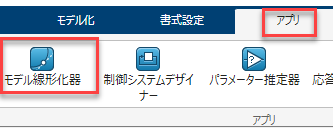

このようなウィンドウが開く。

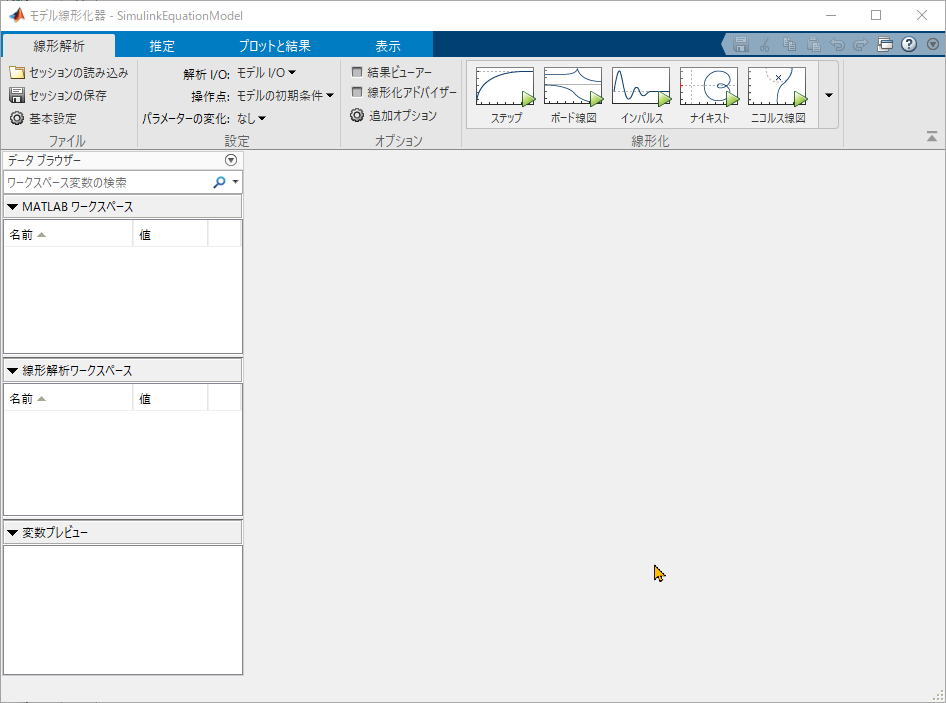

### **操作３：推定のための入力信号作成**

偏微分による線形化をではなく、外部から微小変動として正弦波信号を入力した際に

出力にはその微小変動に伴って出力値が変化する。

正弦波信号は常に一定の振幅・周波数で入力される。

その際に出力に現れる微小変動が、入力された正弦波信号に対してどの程度振幅が変化したかを調べることで、

入力された正弦波周波数におけるゲイン特性を推定することができる。

また、同様に入力された正弦波信号にたいしてどの程度位相が変化したかを調べることで

入力された正弦波周波数における位相特性を推定することができる。

このプロセスを入力される正弦波の周波数を更新しながら逐次繰り返すことで、

離散的な周波数特性データを取得することができる。

いまから行う操作はそのプロセスに必要な「複数の周波数を切り替えながら入力する正弦波信号」を

GUIの操作で簡単に作成する手順である。

１．モデル線形化器アプリの「推定」タブをクリック

２．画面左上部にある「入力信号：新規作成▼」をクリック

３．sinestremを選択

４．一般の周波数単位をHzにする（rad/sで周波数を指定したい場合は変更しなくても良いです）

５．開いたダイアログの「＋」ボタンを押して入力する信号データセットを作成する

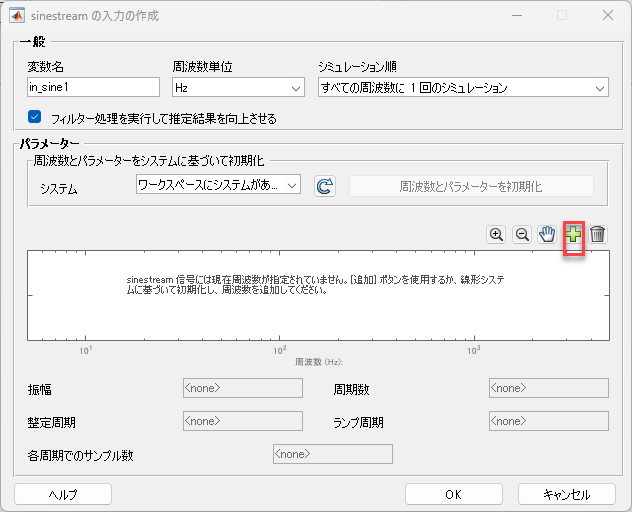

５．周波数の追加ダイアログで周波数の範囲、周波数の数を指定する。

下記のように設定した場合は100~10000Hzの間で30刻みでデータを作成することになります。

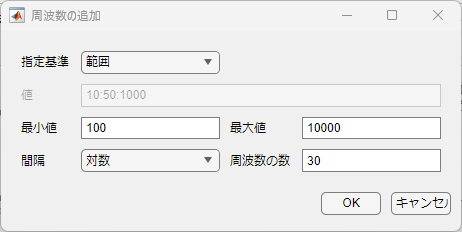

6.各データを下記のようにドラックして選択し、正弦波の振幅などの設定を行い「適応」をクリックする。

（今回は振幅0.01 周期数5 整定周期1 ランプ周期0　サンプル数50と設定します）

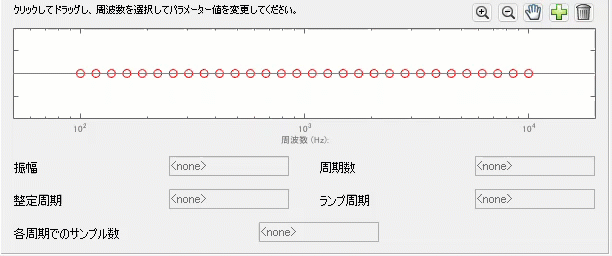

#### Hint:各パラメータの意味合い

対象となるコンバータの出力電力・電圧・電流などの仕様やスイッチング周波数などで

適切なパラメータは異なるため、コンバータの設計者であるユーザが適切なパラメータを選定する必要があります。

## sinestream 入力信号　

[https://jp.mathworks.com/help/slcontrol/ug/creating-sinestream-input-signals.html](https://jp.mathworks.com/help/slcontrol/ug/creating-sinestream-input-signals.html)

上記ヘルプドキュメントの記載をご確認ください。図を含めての解説があるため大変わかりやすいです。

電源回路における補足情報を下記に示します。

**振幅：**

正弦波外乱の振幅を示します。今回の場合DutyからVoutまでの伝達関数を推定しようとしているため、Dutyに対して0.01の微小変化を重畳させることになります。

これが小さすぎるとDutyの変化率が小さすぎるためシミュレーションを実行しても出力のVoutに変化を及ぼさないことがあります。

また、Dutyに関しては変化幅を小さくしすぎることでDuty幅の変化量がシミュレーションのタイムステップより小さくなってしまった場合、

その影響はシミュレーション結果にまったく反映されなくなるため注意が必要です。

一方で振幅を大きくさせすぎると、出力電圧の変化量が大きくなりすぎて正確な測定ができなくなります。

極端な例だと、そもそもDutyはあるスイッチング周期においてON時間の比率を表す値であるため、取りうる値は0~1の範囲ですが、

振幅を"10”と設定してしまうとその範囲を超えた外乱を加えることになり、全く意図通りの結果が得られなくなります。

**周期数：**

各周波数で何周期外乱を入力するかを指定します。

今回の場合だとまず100Hzの信号を重畳しますが、整定周期＋４周期入力したら周波数が切り替わり次の200Hzが重畳されます。

周期を増やすことで推定のための計測データを増やすことに鳴るので、推定の精度向上に貢献する場合があります。

一方である程度のデータ量に達すると推定の精度はほとんど変化しなくなります。それ以上に周期を増やしても単純にシミュレーション時間が長くなるだけなので、

結果をみながら適切な周期数を設定する必要があります。

**整定周期：**

周波数が更新されてから、推定を開始するまでの待ち時間を指定します。

これが１だと、１周期分は外乱を入力するのみで推定は開始されません。次の週期から「周期数」で指定した周期だけ外乱が入力され、その区間を推定データとします。

これは周波数が変化した際に制御対象が一時的に過渡特性として変動する可能性があるため、

その影響を推定データから排除するためにこのパラメータを設定します。

整定周期がながければ推定データに過渡特性のデータが混在するリスクが低くなり、推定の精度が高まることが期待できますが、

周期数と同様にある程度の周期数に達すると推定の精度はほとんど変化しなくなります。

それ以上に周期を増やしても単純にシミュレーション時間が長くなるだけなので、結果をみながら適切な周期数を設定する必要があります。

**ランプ周期：**

こちらに周期を設定すると周波数を切り替える際に非線形に周波数が切り替わるのではなく、

段階的になめらかに変化するようになります。

こちらの周期を増やすと、周波数変化の影響を減らすことができるので整定周期同様推定データに過渡特性のデータが混在するリスクが低くなり、

推定の精度が高まることが期待できますが、ある程度の周期数に達すると推定の精度はほとんど変化しなくなります。

それ以上に周期を増やしても単純にシミュレーション時間が長くなるだけなので、結果をみながら適切な周期数を設定する必要があります。

**各周期でのサンプル数：**

１周期あたりに推定データとして取得するサンプル数です。こちらも増やせば増やすほど精度向上が期待できますが、

高い周波数を重畳させる条件でサンプル数が多くなるとそれだけシミュレーションの刻み幅が細かくなりますのでシミュレーション時間はかなり長くなります。

#### 操作４：定常状態を操作点になるように設定

Script02における２章：定常解（静特性式）の導出で行ったことと等価な作業、

即ち微小振動を入力する前に定常状態である$\mathit{\mathbf{X}}=\left\lbrack \begin{array}{c}
I_L \\
V_c 
\end{array}\right\rbrack$が一定値をもつ状態をアプリで設定する。

一つ前の章である**3.  Simulinkによる微分方程式モデルの定常解（静特性式）の導出**

にて、Simulinkで式をモデリングしてシミュレーションすることで定常解を求められることを示した。

これを利用して、このツールには「シミュレーション実行時間X秒時点の演算結果を定常解とする」

というような指定をする事が可能である。これをこのアプリでは”スナップショットを撮る”という。

下記の通り

- ”操作点：モデルの初期条件”をクリック

- シミュレーションのスナップショットを撮るをクリック

- シミュレーションのスナップショット時間を指定

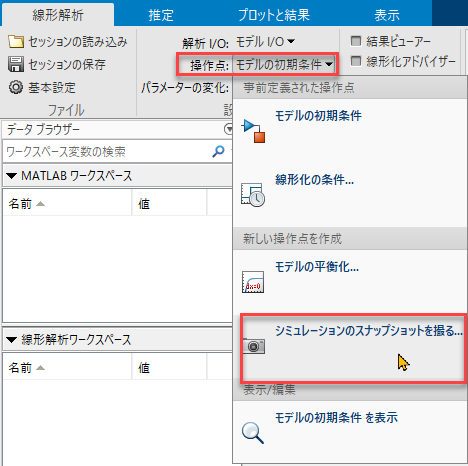

**2.2.3　微分方程式のシミュレーション**で確認したシミュレーション結果から

0.03秒以降であれば十分解が一意の値に収束してい良う見えるので

今回はスナップショット時間を0.03と設定した。

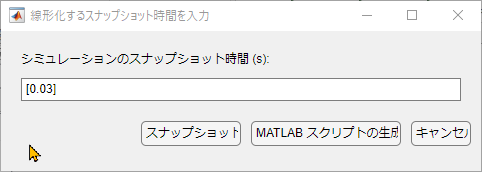

スナップショットボタンをクリックすると

線形化アプリ専用のローカルワークスペースである

線形解析ワークスペースにop_snapshot1というデータが追加される。

アプリ上部の「ステップ、ボード線図、インパルス、ナイキスト、ニコルス線図・・・」等のプロットをクリックすれば

アプリが定常解近傍での線形化を実施し、指定したグラフをプロットする。

プロット画面右端の▽ボタンをクリックすることですべての操作ボタンを閲覧できる。

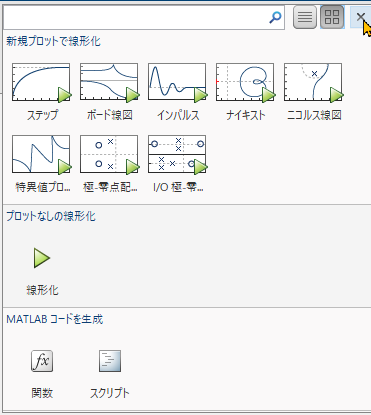

ここで「ボード線図」をクリックすると下記の通り取得ができた。

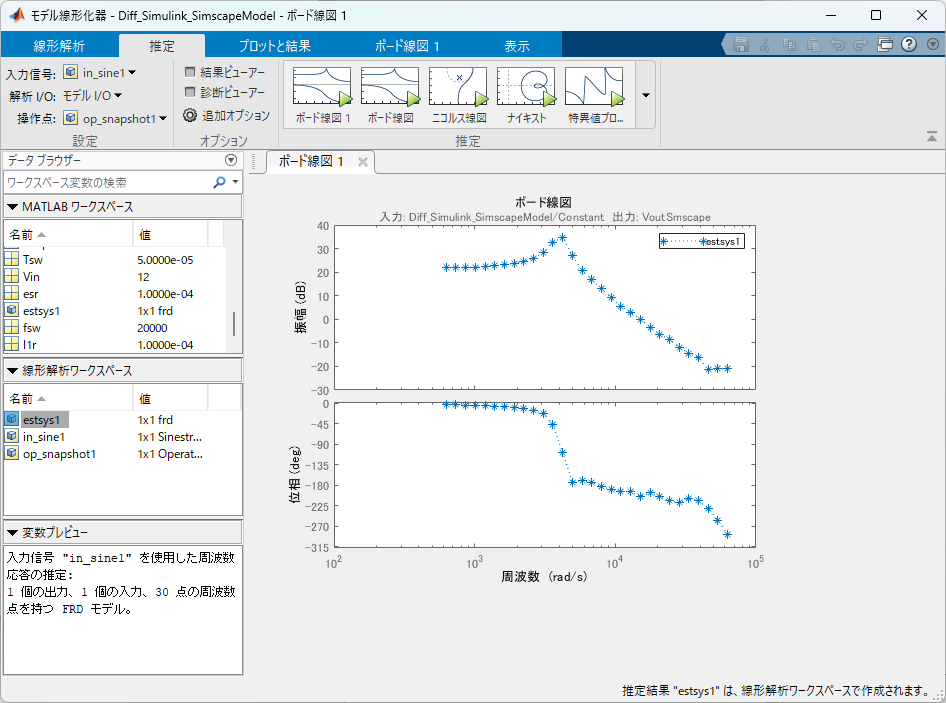

モデルのシミュレーション結果をScopeで観測しても、段階的に周波数を切り替えながらDutyを変化させ、その影響が電流および電圧にあらわれていることが見て取れる。

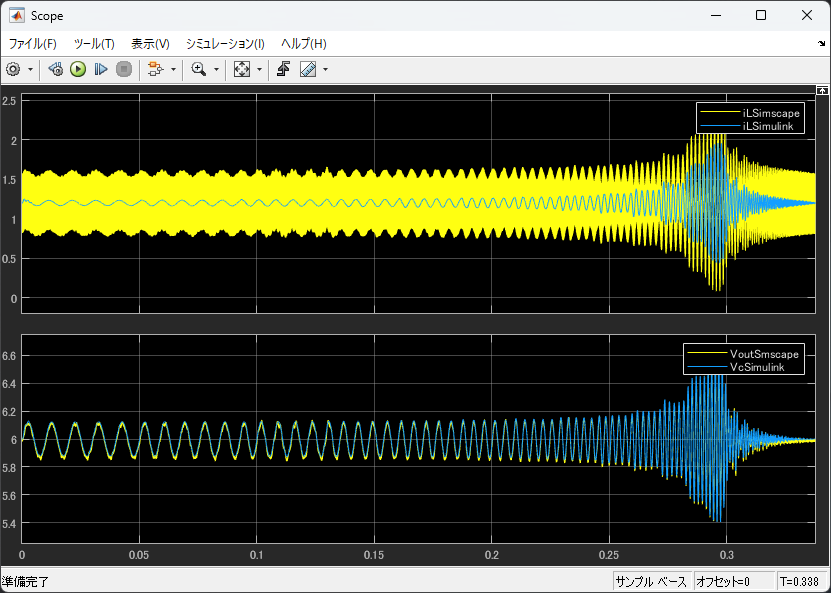

#### 操作５:代数式演算の結果と比較

Script02で求めたSymbolic式データをロードする。

load('SymbolicEquation.mat');

アプリで線形化された結果は

線形化アプリ専用のローカルワークスペースである

線形解析ワークスペースにop_snapshot1というデータが追加される。

こちらをMATLABワークスペースにドラッグ・アンド・ドロップすれば、データが

MATALBのワークスペースにコピーされてスクリプトから操作できるようになる。

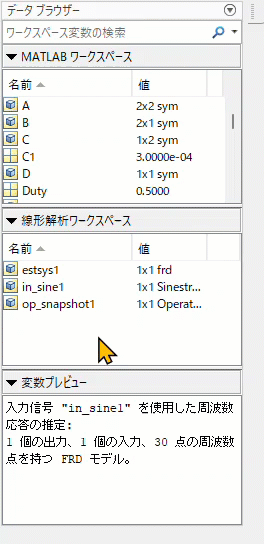

**コピーされた変数名が”estsys1"以外ならば下記スクリプトの都合上名前を"estsys1"にリネームすること。**

**そのデータが無いとこの後のスクリプトはエラーで止まってしまいます。**

代数式モデルとアプリで取得した線形化結果を比較する。結果は概ね理論と一致している。

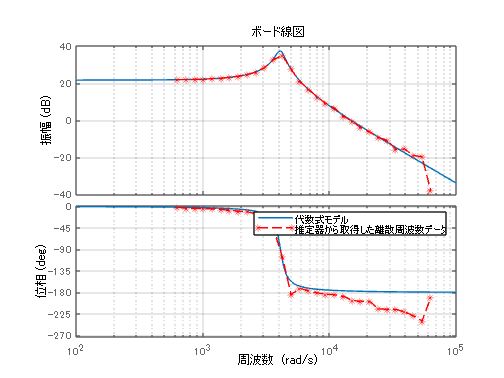

%Symbolic式を伝達関数モデルに変換
Gplant_s = arrayfun(@sym2tf_ykamatan,subs(GdXdDuty),'UniformOutput',false);

%各要素のボード線図を描画
figure;
bodeplot(Gplant_s{2,1});
grid on;
hold on;
bodeplot(estsys1,'--*r');

legend('代数式モデル','推定器から取得した離散周波数データ')

高周波領域で位相特性が一致していない部分についてはむだ時間遅れの影響が理論モデルには反映されていない一方

Simscapeモデル側はPWMによるスイッチングの挙動含めてモデリングがされているため、

Duty値の更新とパルス反映までのむだ時間が表現されておりその影響が現れている。

PWMのスイッチング周期を$T_{\textrm{sw}}$とするとむだ時間の影響は


$$G_{\textrm{delay}} \left(s\right)=e^{-{\textrm{sT}}_{\textrm{sw}} } \;$$


である。

これは外乱の影響における最悪値を示している。

すなわちPWMデューティを更新した直後に外乱が発生した場合、その反映は最大Tsw時間経過したあとになることを示している。

そのため、外乱の発生タイミングに応じてこのむだ時間は変化することになる。

ここで外乱の発生タイミングが一様にばらついていると想定すると、平均的には遅延時間$\frac{1}{2}T_{\textrm{sw}}$となるはずである。

そのため実際には実機での計測結果も概ね下記式に従う。


$$G_{\textrm{delay}} \left(s\right)=e^{-{s\;\frac{1}{2}T{\textrm{sw}} } } \;$$


**＃注意事項として実機の計測結果と一致させる目的であれば**$\frac{1}{2}T_{\textrm{sw}}$**が概ね妥当であるが、設計の最悪値としてはむだ時間を**$T_{\textrm{sw}}$**とするのが最も保守的な設計である。**

下記コードでボード線図の一致性を確認する。結果からも位相の遅れはむだ時間による影響である可能性が高いとうかがえる。

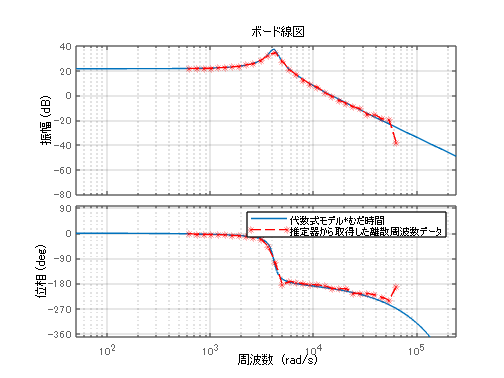

load('SymbolicEquation.mat');
%Symbolic式を伝達関数モデルに変換
Gplant_s = arrayfun(@sym2tf_ykamatan,subs(GdXdDuty),'UniformOutput',false);

s = tf('s');
Gdelay = exp(-s*Tsw*0.5);

%各要素のボード線図を描画
figure;
bodeplot(Gplant_s{2,1}*Gdelay);
grid on;
hold on;
h =bodeplot(estsys1,'--*r');
legend('代数式モデル*むだ時間','推定器から取得した離散周波数データ')
p = getoptions(h);
p.XLim = {[50, 240000]};
p.YLim = {[-80, 40];[-370, 100]};
setoptions(h,p);

#### 離散値としての周波数データから連続系の伝達関数への変換

今回の例では取得したデータを離散データのままPlotしていますが、

この離散データにフィットする連続の伝達関数モデルを推定したい場合は　

System Identification Toolboxが提供する [tfes](https://jp.mathworks.com/help/ident/ref/tfest.html)t関数を用いることで

推定した周波数特性離散データに最大限一致する連続系伝達関数の係数値を推定が可能です。

第一引数に 今回推定した周波数特性の離散データが格納されている”estsys1”を指定し、

第二引数にフィッティングしたい伝達関数の極数、

第三引数にフィッティングしたい伝達関数の零点数を入力します。

もし、むだ時間を含めて推定結果を出したい場合は第四引数にむだ時間を指定します。

estTf = tfest(estsys1,3,1,Tsw/2)

estTf =
  入力 "Diff_Simulink_SimscapeModel/Constant" から出力 "VoutSmscape":
                            1.805e08 s + 9.345e11
  exp(-2.5e-05*s) * --------------------------------------
                    s^3 + 5132 s^2 + 2.093e07 s + 7.461e10
 
同定された連続時間伝達関数です。

パラメーター化:
   極の数: 3   零点の数: 1
   自由係数の数: 5
   パラメーターとその不確かさについては、"tfdata"、"getpvec"、"getcov" を使用してください。

状態:                                                           
周波数応答データ "入力信号 "in_sine1" を使用した周波数応答の推定" に TFEST を使用して推定されました。
推定データへの適合: 86.02%                                             
FPE: 6.746, MSE: 4.818                                        
 
モデル プロパティ


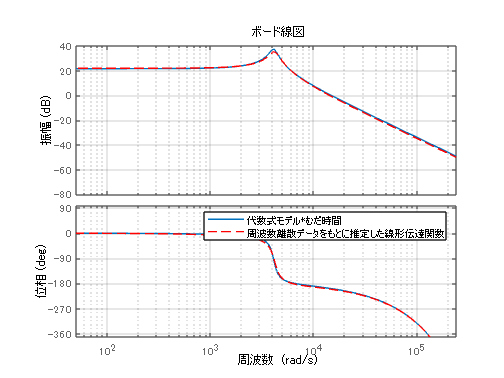


figure;
bodeplot(Gplant_s{2,1}*Gdelay);
grid on;
hold on;
h =bodeplot(estTf,'--r');
legend('代数式モデル*むだ時間','周波数離散データをもとに推定した線形伝達関数')
p = getoptions(h);
p.XLim = {[50, 240000]};
p.YLim = {[-80, 40];[-370, 100]};
setoptions(h,p);

上記の通り、代数式モデルともよく一致する連続系伝達関数が

Simscapeの回路モデルから取得できることがわかります。

このアプローチは新規で回路トポロジーを検討する際に、理論上の伝達関数が求まらない場合、

Simulation上でのデータをベースとして伝達関数を推定する必要がある祭に有効なアプローチとなります。

詳しくはヘルプドキュメントをご確認くださいませ。

#### コマンド ラインでの伝達関数モデルの推定(EN)

[https://jp.mathworks.com/help/ident/ug/how-to-estimate-transfer-function-models-at-the-command-line.html](https://jp.mathworks.com/help/ident/ug/how-to-estimate-transfer-function-models-at-the-command-line.html)

#### 与えられた周波数応答データに適合する伝達遅延をもつ伝達関数モデルの推定(EN)

[https://jp.mathworks.com/help/ident/ug/estimate-transfer-function-models-with-transport-delay-to-fit-given-frequency-response-data.html](https://jp.mathworks.com/help/ident/ug/estimate-transfer-function-models-with-transport-delay-to-fit-given-frequency-response-data.html)

## 4.パラメータを更新して再度シミュレーション(電流不連続モードの存在）

ここではわざと状態平均化法の前提を崩すような回路を作って

今回作成した状態平均化モデルが有効でないケースの存在を明らかにする。

コンバータには電流連続モード、電流不連続モードという回路動作モードがある。

このモードは互いに伝達関数が異なる。[1]

この回路はHighサイドとLowサイドが相補にスイッチングするようにモデリングされているため、

電流の逆流が許容されるため、常に連続モードで動作する。

今回はLowサイドのMOSFETゲートしきい値電圧を意図的に引き上げて

ボディダイオードだけが動作するようにする。すると回路動作が電流不連続モードとなり

電流連続モードを前提としたSimulinkモデルとの不一致が確認できる。

LowVth = 20;

Simdata = sim("Model\Script04_Model\Diff_Simulink_SimscapeModel.slx");


figure;
for i = 1:2
    subplot(2,1,i)
    Simdata.ScopeData{i}.Values.plot()
    grid on;
end
subplot(2,1,1)
ylabel('IL')
legend('Simscape','Simulink');
subplot(2,1,2)
legend('Simscape','Simulink');
ylabel('Vout')

想定通り全く一致していない。

一致してない部分のうちコイル電流部分だけクローズアップしてみると

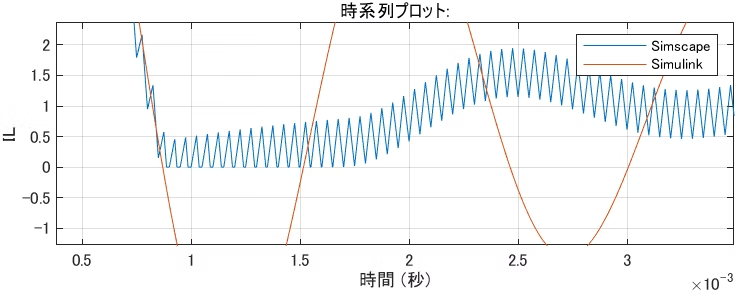

たしかに電流が0で底打ちになっていて逆流していないので

ダイナミクスが切り替わっている事がわかる。

#### 不連続モードのときは状態平均化モデルは使えないのだろうか？

そんなことはない。

連続モードの状態平均化モデルはそのまま使えないのですが

このような違いはすでに議論をされていて、参考文献[1]では不連続モードを

- ターンオン期間

- ターンオフ期間

- ターンオフかつ電流も０で底打ちしてる期間

の３状態で分離して計算し３つを各Duty比で重み付けしたらちゃんと不連続モードで状態平均化モデルを作れることが述べられている。

## まとめ

このサンプルでは１～４を通じて理論ベースの数式とブロック線図モデル、そしてSimscapeを用いた回路モデルを作成し、

その一致性を確認することを述べてきた。

同じコンバータの動作を示す一見”同じ”モデルである一方、それぞれのモデルには特徴があり

それらの特徴をうまく活用すれば理論から回路シミュレーションまで一貫してつながった設計が可能であることを示した。

このような設計を助けるツールとしてMathWorksツールを活用いただければ幸いである。

## Reference

[1] 阿部　征哉, 財津　俊行, 上松 武.　デジタル電源の基礎と設計法 -スイッチング電源のデジタル制御-. 科学情報出版株式会社, 2020,246p, ISBN978-4-904774-84-7.

[2] Frede Blaabjerg, ed. Yanfelng Shen, Zian Qi and Huai Wang. Control of Power Electronic Converters And Systems. Volume 1, Chapter 3 "Modeling and Control of DC-DC Converters" p69-p92, Academic Press, 2018, ISBN 978-0-12-804254-7.

[3] コンバータ制御設計に役立つ状態平均化モデルをsimulinkで書いてみた4 [https://qiita.com/griffin921/items/87dcda9ba1879cca1181](https://qiita.com/griffin921/items/87dcda9ba1879cca1181)

[4][パワーエレクトロニクスシステムの複合的モデリングとシミュレーション技術調査専門委員会](http://www2.iee.or.jp/~dspc/PESim/index.html) **パワエレシミュレーション（PE-Sim）において使用されるシミュレータの特徴一覧表 **[http://www2.iee.or.jp/~dspc/PESim/simulators.html](http://www2.iee.or.jp/~dspc/PESim/simulators.html)